# Exercise 6.1 - Fourier Transform

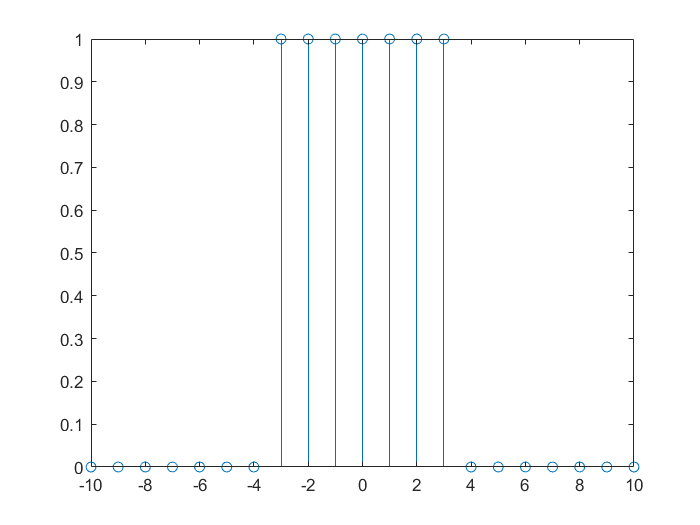

% Define the sequence x[n].
n = -10 : 10;
x = zeros(1, 21);
x(8 : 14) = 1;

% Plot x[n].
stem(n, x);

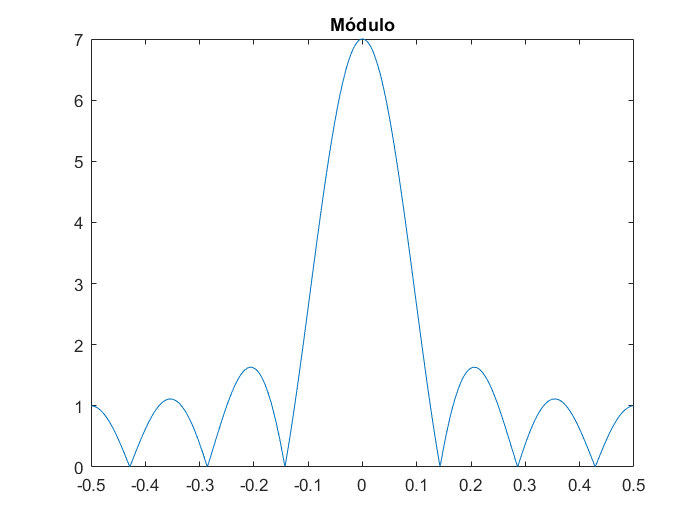


% Calculate the Fourier Transform.
N = 1024;
spectrum = fft(x, N);
spectrumShifted = fftshift(spectrum); % Shift spectrum to the origin.

% Narrow down frequencies of the OX axis.
f = (0 : (N-1)) / N - 0.5;

% Plot the amplitude and phase of the transform.
plot(f, abs(spectrumShifted)), title('Amplitude');

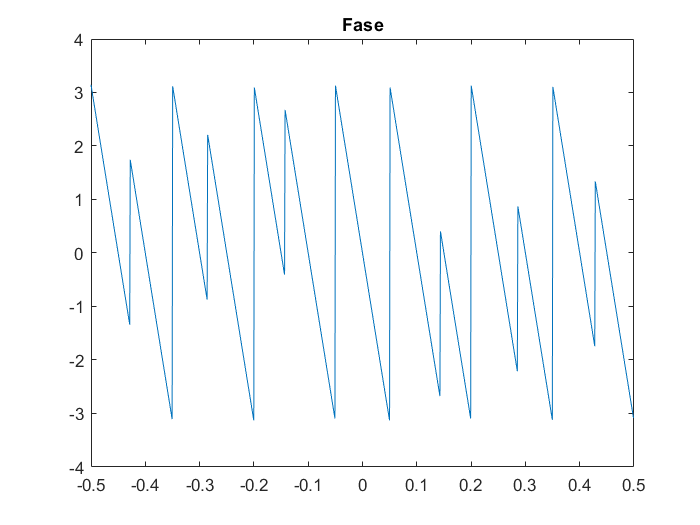

plot(f, angle(spectrumShifted)), title('Phase');

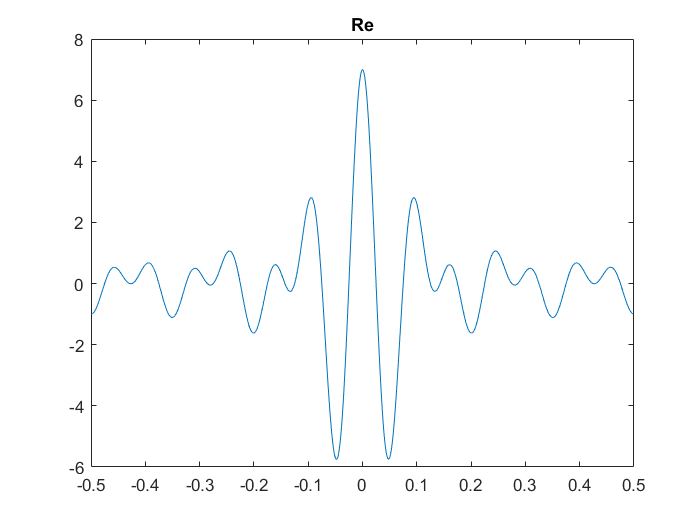


% Plot the real and imaginary parts.
plot(f, real(spectrumShifted)), title('Re');

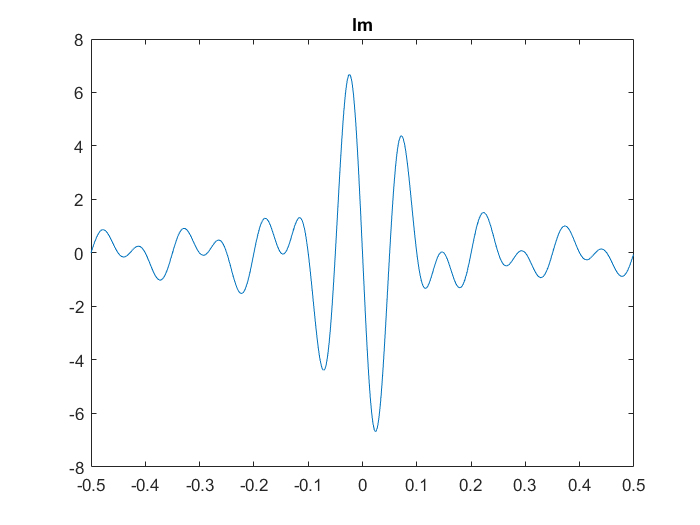

plot(f, imag(spectrumShifted)), title('Im');